ECE 537 

Exercise #5

Group 5

Muqian Gui ----- V00870654

Hang Ruan ----- V00923058

clc;
clear all;
close all;


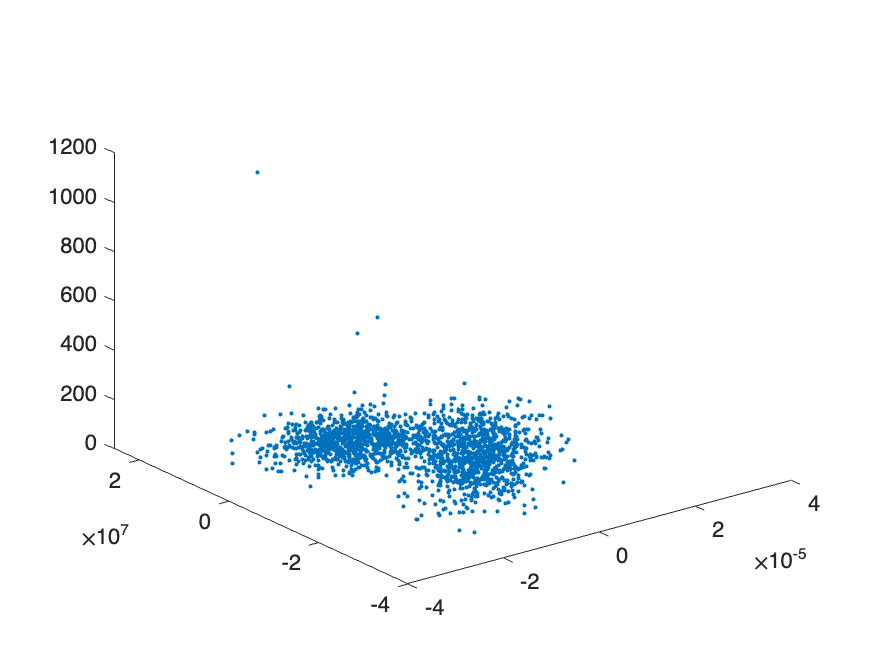

% Q1
load("Exercise_6_data.mat");
plot3(data(:,1), data(:,2), data(:,3),'.');

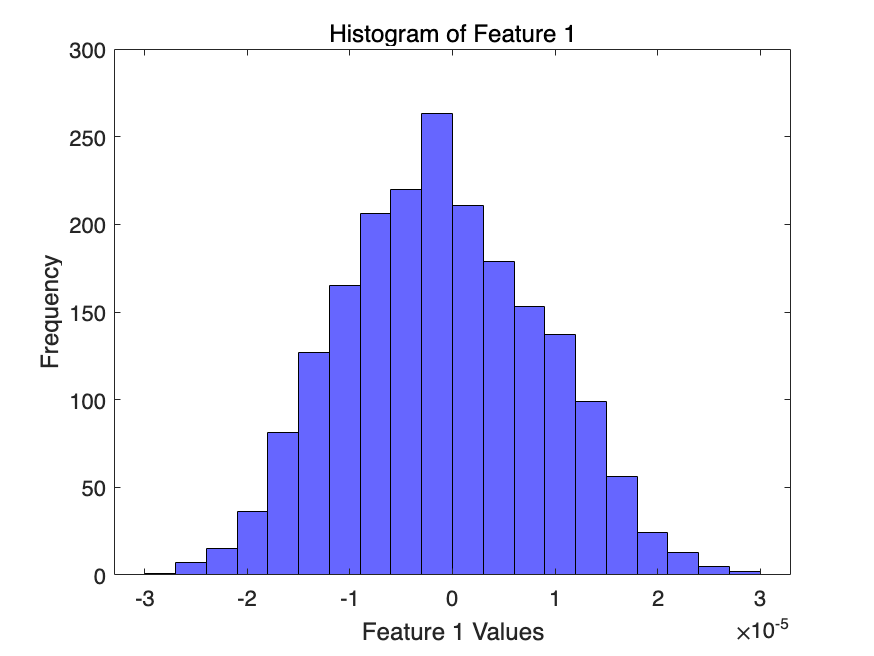

% Q2
% Generate the hist graph for each features to visiualize first to find out the scale for each feature.
% Then determine the measurement feature from that point
x = data;
% Generate histogram plots for each feature
histogram(x(:, 1), 'FaceColor', 'blue');
title('Histogram of Feature 1');
xlabel('Feature 1 Values');
ylabel('Frequency');

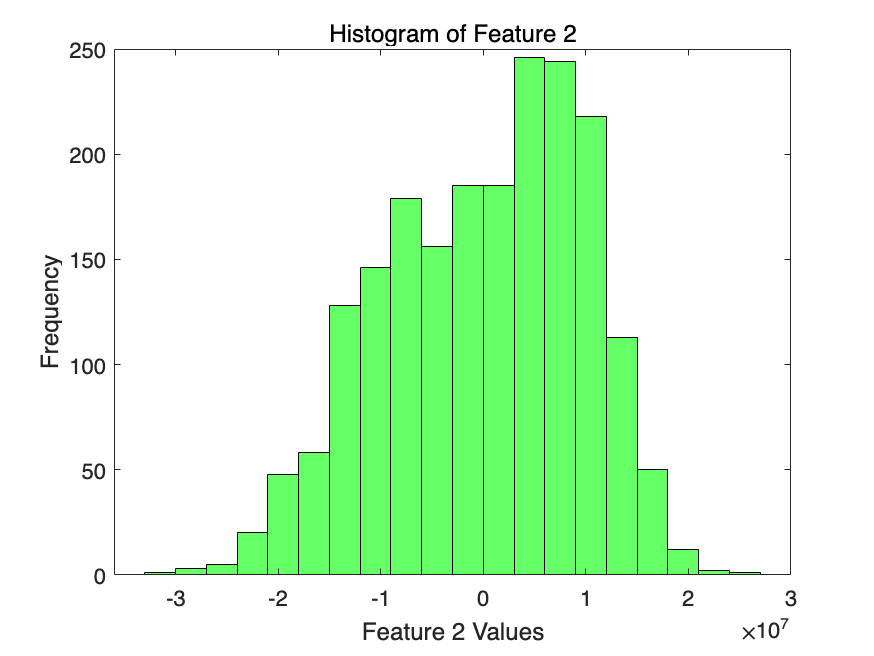


histogram(x(:, 2), 'FaceColor', 'green');
title('Histogram of Feature 2');
xlabel('Feature 2 Values');
ylabel('Frequency');

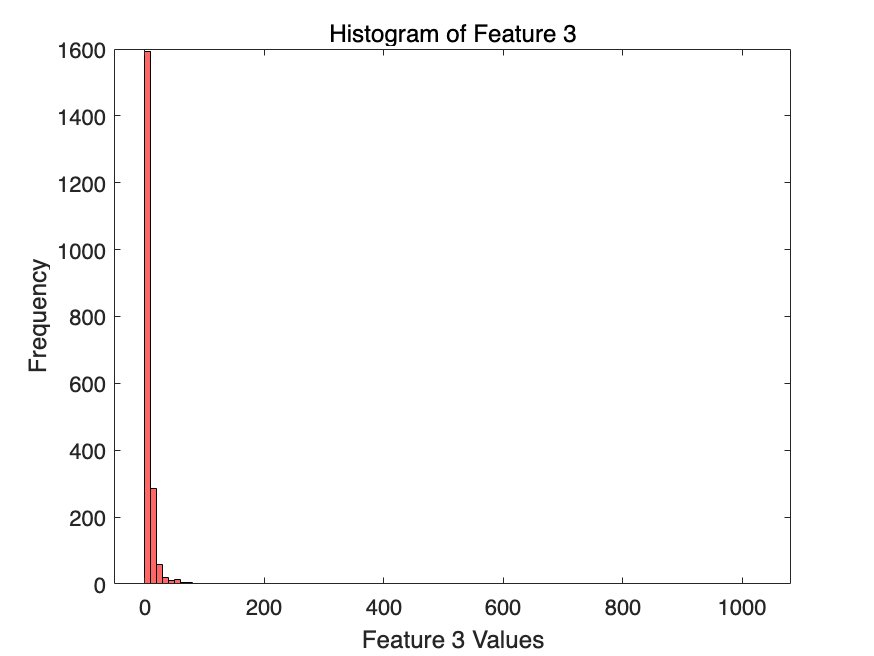


histogram(x(:, 3), 'FaceColor', 'red');
title('Histogram of Feature 3');
xlabel('Feature 3 Values');
ylabel('Frequency');


feature_scale = zeros(1, size(x, 2));  % Initialize feature scale vector
for dim = 1:size(x, 2)
    feature_scale(dim) = max(x(:, dim)) - min(x(:, dim));
end

% Display the feature scale for each dimension
disp('Feature scale for each dimension:');

Feature scale for each dimension:


disp(feature_scale)

   1.0e+07 *

    0.0000    5.5736    0.0001



% Q3
fe1 = rescale(data(:,1),-1,1);
fe2 = rescale(data(:,2),-1,1);
fe3 = rescale(data(:,3),-1,1);
x_normalize = horzcat(fe1,fe2,fe3);


Using the range [-1,1], the magnitude represents the relative distance within the range. It's also benefitial when the data distribution is symmetric and negative values can tell information.

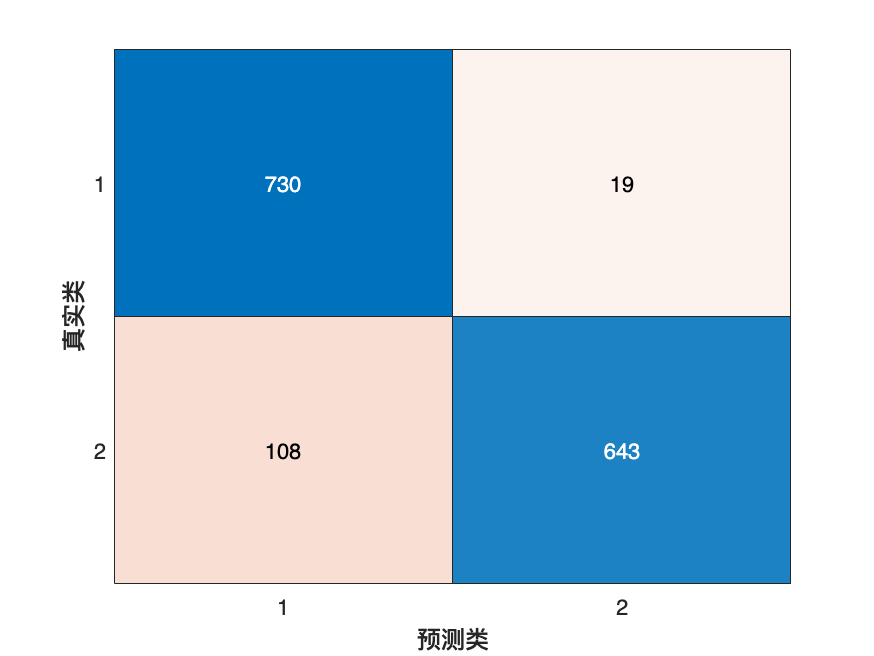

cm =   ConfusionMatrixChart - 属性:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  显示 所有属性


% Q4 

[train_idx,val_idx,test_idx] = dividerand(2000,0.25,0,0.75);
train_data = x_normalize(train_idx,:);
test_data = x_normalize(test_idx,:);

train_label = class(train_idx);
test_label = class(test_idx);


mdl = fitcnb(train_data,train_label );
pre = predict (mdl,test_data);

cm = confusionchart(test_label, pre)

percentErrors_bay = sum(pre' ~= test_label)/numel(test_label)

percentErrors_bay = 0.0847

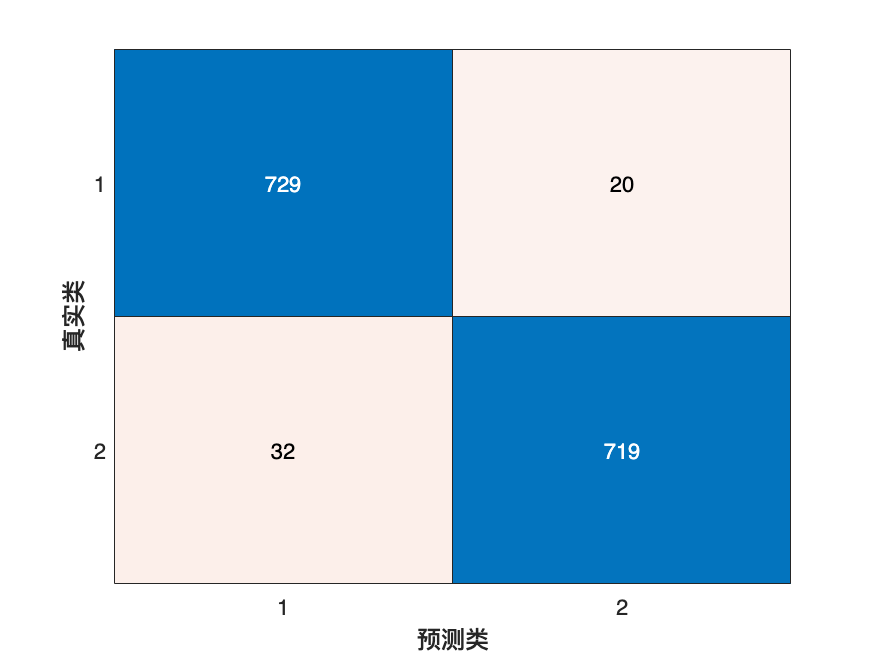

cm_nn =   ConfusionMatrixChart - 属性:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  显示 所有属性


% Neuro Network
% Onehot encoder for label
train_label_onehot = double(train_label' == 1:2)';
test_label_onehot = double(test_label' == 1:2)';



trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
% Create a Pattern Recognition Network
hiddenLayerSize = 10;
clear patternnet;
net = patternnet(hiddenLayerSize, trainFcn);
net.inputs{1}.processFcns = {};
[net,tr] = train(net,train_data',train_label_onehot); % Train the Network
y = net(test_data'); % Predicted value from Neuro Network
yind = round(y);
yind = vec2ind(yind);
tind = test_label;

cm_nn = confusionchart(tind, yind)

percentErrors = sum(yind ~= tind)/numel(tind)

percentErrors = 0.0347

% Q5
distributionParams = mdl.DistributionParameters;
classNames = mdl.ClassNames;
nClasses = numel(classNames);


weights = net.IW{1};
weights_sum = sum(abs(weights));


Bayes classifier is doing better than neural network in classification of our normalized data. Neural network and bayes classifier uses feature 3 to dominate the classification process.

Q6

Normalizing data linearly such as scaling feature to [-1,1] ignores the underlying distrubtion. For example, some data needs to be transformed logarithmically or exponentially. 

Scaling data linearly is also sensitive to outliers and it can distort the overall distrubtion.

Scaling data linearly doesn't takes inter-feature relationships into account and can potentially breaks their relationships.

Q7 

To perform data normalization, we need first understand the data distrubtion and identify any outliers, or non-linear relationships in the data. We need to choose normalization techniques(Min-Max Scaling, Z-score, log scaling, exponential scaling) appropriately based on the data characteristics. We also need to address any outliers exist in our data.

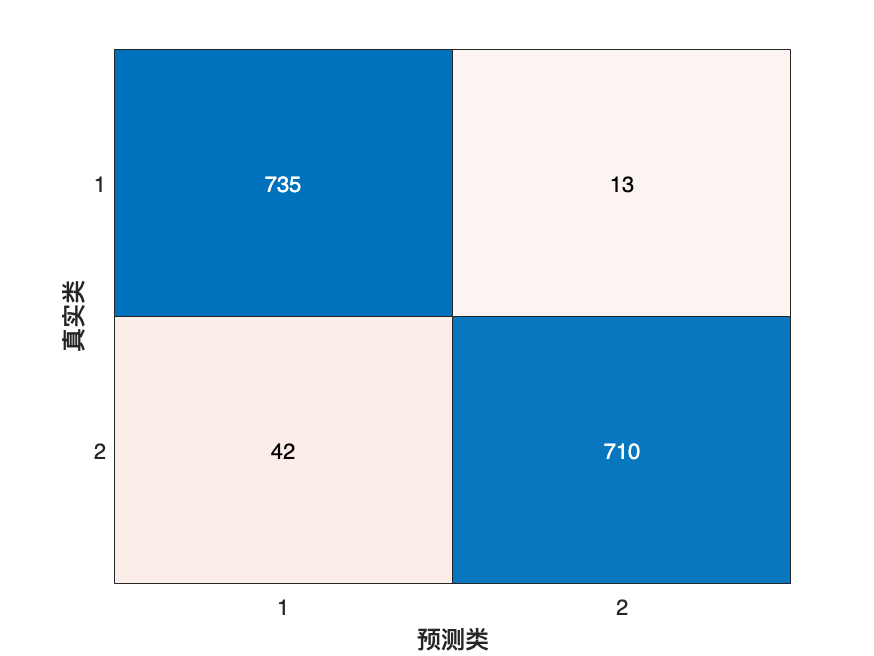

cm =   ConfusionMatrixChart - 属性:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  显示 所有属性


%Q8

x_normalize = normalize(data);
% fe1 = rescale(x(:,1),-1,1);
% fe2 = rescale(x(:,2),-1,1);
% fe3 = rescale(x(:,3),-1,1);
% x_normalize = horzcat(fe1,fe2,fe3);
[train_idx,val_idx,test_idx] = dividerand(2000,0.25,0,0.75);
train_data = x_normalize(train_idx,:);
test_data = x_normalize(test_idx,:);

train_label = class(train_idx);
test_label = class(test_idx);


mdl = fitcnb(train_data,train_label );
pre = predict (mdl,test_data);

cm = confusionchart(test_label, pre)

percentErrors_bay = sum(pre' ~= test_label)/numel(test_label)

percentErrors_bay = 0.0367

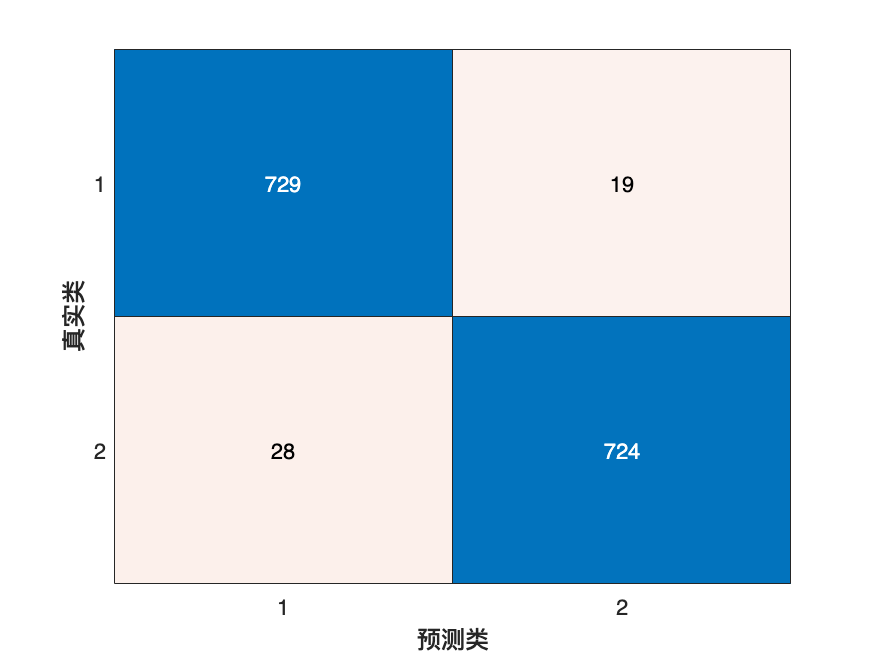

cm_nn =   ConfusionMatrixChart - 属性:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  显示 所有属性


% Neuro Network
% Onehot encoder for label
train_label_onehot = double(train_label' == 1:2)';
test_label_onehot = double(test_label' == 1:2)';



trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
% Create a Pattern Recognition Network
hiddenLayerSize = 10;
clear patternnet;
net = patternnet(hiddenLayerSize, trainFcn);
%net.inputs{1}.processFcns = {};
[net,tr] = train(net,train_data',train_label_onehot); % Train the Network
y = net(test_data'); % Predicted value from Neuro Network
yind = round(y);
[yind,~] = find(yind);
yind = yind';
tind = vec2ind(test_label_onehot);

cm_nn = confusionchart(tind, yind)

percentErrors = sum(yind ~= tind)/numel(tind)

percentErrors = 0.0313

neural network error and Bayes error has decreased versus the the original linearlly normalized data.